# **ASL American Sign Language Detection using Bayesian Networks and Convolutional Neural Networks**

## Course “Advanced Data Analysis and Machine Learning”

### **Project work 2**

### Authors: 

#### Thanh Tran (000285359)

#### Nghia Nguyen (000275466)

#### Swapnil Baad (000323486)

Report can be accessed with read-only priviledge from [Group_ASL_A2_report.docx](https://lut-my.sharepoint.com/:w:/g/personal/thanh_tran_student_lut_fi/ERNxVSaZ6XhNpJh_Ecmp26oBOtcaGtWC5TtH-ybKX2-_Uw?e=hczf4M)

## SETUP

% Add path to BNT toolbox
path_to_BNT = "C:\Users\thanh\bnt";
addpath(genpath(path_to_BNT));

folderPath = 'C:\Users\swapn\Downloads\bnt-master\bnt-master';
addpath(genpath(folderPath))

% Add services folder containing helper functions
addpath('./services');
% Add extracted data folder
addpath('./extracted_features');

Training_data_loading = false;
Testing_data_loading = false;
Feature_extraction_1_example = false;
Feature_extraction_1_actual = false;    % This step takes 5hours
Feature_extraction_2_example = false;
Feature_extraction_2_actual = false;    % This step takes even more. Therefore, extracted data has been saved for later use.
Data_transformation = false;

## IMPORT DATA

### 1 Loading Training data

if Training_data_loading
    % Define environment variables
    class_list = ["K", "L", "M", "N", "O", "P", "Q", "R", "S", "T"];                                    % All classes included in this project
    class_list = sort(class_list);
    nClass = length(class_list);                                 % The number of classes included
    
    
    train_data_path = "./data/asl_alphabet_train/asl_alphabet_train";                                  % File path to the directory of train data
    
    % Load images and convert to RGB data matrices
    Xtemplates_filename = {};
    Ytemplates = [];
    Xtrain = {};
    Ytrain = [];
    nTrainSamplePerClass = zeros(nClass, 1);
    disp("Training data loading ...");

    for c = 1:nClass    
        class_dir = sprintf(train_data_path + "/" + class_list(c));
        file_list = dir(class_dir);
        file_list = file_list(3:end);
        nImage = length(file_list);
        nTrainSamplePerClass(c) = nImage;
        for i = 1:nImage
            path_to_image = sprintf(class_dir + "/" + file_list(i).name);
            image_RGB = imread(path_to_image);
            image_gray = rgb2gray(image_RGB);
            Xtrain{end+1} = image_gray;
            Ytrain = [Ytrain; class_list(c)];
            
            % Get one every 100 images per class and save as templates of class
%             if ismember(i, 1:100:nImage)
%                 Xtemplates_filename{end+1} = path_to_image;
%                 Ytemplates = [Ytemplates, class_list(c)];
%             end
    
        end
    
        fprintf('   Class %s loading done.\n', class_list(c));
    end

%     save extracted_features\templates.mat Xtemplates_filename Ytemplates
    
%     save extracted_features\Ytrain.mat Ytrain

    nXtrain = length(Xtrain);
    Cum_nTrainSamplePerClass = cumsum(nTrainSamplePerClass);
end

### 2 Loading testing data

if Testing_data_loading
    test_data_path = "./data/asl_alphabet_test/asl_alphabet_test";                                     % File path to the directory of test data
    Xtest = {};
    Ytest = [];
    nTestSamplePerClass = zeros(nClass, 1);
    disp('Testing data loading ...');
    
    file_list = dir(test_data_path);
    file_list = file_list(3:end);
    regex_class = sprintf('%s-%s', class_list(1), class_list(end));
    regex_file_name = sprintf('^(?<file_name>[%s]_test.jpg)', regex_class);
    test_files_cell = regexpi({file_list.name}, regex_file_name, 'names','lineanchors');
    test_files = vertcat(test_files_cell{:})
    nXtest = length(test_files);
    
    for f = 1:nXtest
        file_name = test_files(f).file_name;
        
        path_to_image = sprintf(test_data_path + "/" + file_name);
        image_RGB = imread(path_to_image);
        image_gray = rgb2gray(image_RGB);
        Xtest{end+1} = image_gray;
        Ytest = [Ytest; file_name(1)];
    end
end

## FEATURE EXTRACTION

### 1 Hand segmentation and SIFT Feature Extraction

#### 1.1 Examples with visualization

if Feature_extraction_1_example && Training_data_loading
    nExample = 1;
    nExampleClass = 3;
    for c = 1:nExampleClass
        fprintf('Class %s feature extracting example(s):\n', class_list(c));
        sample_idxs = find(Ytrain == class_list(c), nExample);
        for i = 1:nExample
            SIFT_points = bound_key_region(Xtrain{sample_idxs(i)}, true);
        end
    end
end

#### 1.2 Actual Extraction

Xtrain_SIFTPoints_var_name = {'SP1x','SP1y','SP2x','SP2y','SP3x','SP3y','SP4x','SP4y','SP5x','SP5y'};

if Feature_extraction_1_actual && Training_data_loading
    nSIFTPoints = 5;
    Xtrain_SIFTPoints = zeros(nXtrain, nSIFTPoints*2);
    for i = 1:nXtrain
        SIFT_points = bound_key_region(Xtrain{i});
        Xtrain_SIFTPoints(i,1:length(SIFT_points)) = SIFT_points;
        if ismember(i, Cum_nTrainSamplePerClass)
            fprintf('   Class %s feature extracting done.\n', Ytrain(i));
        end
    end
    
%     save extracted_features\Xtrain_SIFTPoints.mat Xtrain_SIFTPoints
end

### 2 Matched SURF Feature counts

#### 2.1 Examples with visualization

if Feature_extraction_2_example && Training_data_loading
    nExample = 1;
    nExampleClass = 3;
    for c = 1:nExampleClass
        fprintf('Class %s feature extracting example(s):\n', class_list(c));
        sample_idxs = find(Ytrain == class_list(c), nExample);
        for i = 1:nExample
            bestnMatches = get_best_nMatchedFeatures(Xtrain{sample_idxs(i)}, true);
        end
    end
end

#### 2.2 Actual Extraction

Xtrain_nMatchedFeatures_var_name = {'MFK','MFL','MFM','MFN','MFO','MFP','MFQ','MFR','MFS','MFT'};

if Feature_extraction_2_actual && Training_data_loading
    load extracted_features\templates.mat Xtemplates_filename Ytemplates
    TemplateClasses = unique(Ytemplates);
    nTemplateClasses = length(TemplateClasses);

    Xtrain_nMatchedFeatures = zeros(nXtrain,nTemplateClasses);
    for i = 1:nXtrain
        Xtrain_nMatchedFeatures(i,:) = get_best_nMatchedFeatures(Xtrain{i}, false);
    end
    
%     save extracted_features\Xtrain_nMatchedFeatures.mat Xtrain_nMatchedFeatures
end

## EXTRACTED DATA TRANSFORMATION

if Data_transformation
    SIFT_FEATURES_FILE = ".\extracted_features\Xtrain_SIFTPoints.mat";
    Xtrain_SIFTPoints_var_name = {'SP1x','SP1y','SP2x','SP2y','SP3x','SP3y','SP4x','SP4y','SP5x','SP5y'};
    
    SUFTCOUNT_FEATURES_FILE = '.\extracted_features\Xtrain_nMatchedFeatures.mat';
    Xtrain_nMatchedFeatures_var_name = {'MFK','MFL','MFM','MFN','MFO','MFP','MFQ','MFR','MFS','MFT'};
    
    Xtrain_SIFTPoints_table = load_data_and_transform_to_table(SIFT_FEATURES_FILE, 'Xtrain_SIFTPoints', Xtrain_SIFTPoints_var_name, true);
    Xtrain_nMatchedFeatures_table = load_data_and_transform_to_table(SUFTCOUNT_FEATURES_FILE, 'Xtrain_nMatchedFeatures', Xtrain_nMatchedFeatures_var_name, false);
    
%     save extracted_features\Xtrain_SIFTPoints_table.mat Xtrain_SIFTPoints_table
%     save extracted_features\Xtrain_nMatchedFeatures_table.mat Xtrain_nMatchedFeatures_table
    
    Xtrain_extracted = [Xtrain_SIFTPoints_table Xtrain_nMatchedFeatures_table];
%     save extracted_features\Xtrain_extracted.mat Xtrain_extracted
end



## BAYESIAN NETWORK TRAINING AND CALIBRATION

% load extracted_features\Xtrain_extracted.mat Xtrain_extracted
load extracted_features\Xtrain_nMatchedFeatures_table.mat Xtrain_nMatchedFeatures_table
Xtrain_extracted = Xtrain_nMatchedFeatures_table;
load extracted_features\Ytrain.mat Ytrain

% USE VARIABLE NAMED Xtrain_extracted AS TRAINING AND VALIDATING DATA
[nXtrain, nCol] = size(Xtrain_extracted);
% varLabels = ["SP1x", "SP1y", "SP2x", "SP2y", "SP3x", "SP3y", "SP4x", "SP4y", "SP5x", "SP5y","MFK","MFL","MFM","MFN","MFO","MFP","MFQ","MFR","MFS","MFT", "Label"];
varLabels = ["MFK","MFL","MFM","MFN","MFO","MFP","MFQ","MFR","MFS","MFT", "Label"];
class_list = ["K", "L", "M", "N", "O", "P", "Q", "R", "S", "T"];                                    % All classes included in this project
class_list = sort(class_list);

X_train = table2array(Xtrain_extracted);
X_train(:,end+1) = grp2idx(categorical(Ytrain));

% Check NAN
[NAN_r, NAN_c] = find(isnan(X_train));
removed_rows = unique(NAN_r);
X_train(removed_rows,:) = []; 

% Calibration variables
nSeg_cal = 5:10;
nSeg_chosen = 9;
nSeg_cal_N = length(nSeg_cal);

partition_rate_cal = 0.3:-0.05:0.1;
partition_rate_chosen = 0.1;
partition_rate_cal_N = length(partition_rate_cal);

ACCURACY_CAL = zeros(nSeg_cal_N,partition_rate_cal_N);

% Calibrate number of segments (discretization)
for nseg_i = 1:nSeg_cal_N
    try
        clear dataPoint
        clear seg
        clear variable
        clear evidence
    end
% Discretization

nseg = nSeg_cal(nseg_i);
% nseg = nSeg_chosen;              % CHOSEN
X_train_Descrt = zeros(size(X_train));

seg_mat = zeros(nseg, size(X_train,2));
for i = 1:length(X_train(1,1:end-1))
    var     = X_train(:,i);

    minVal  = min(var);
    maxVar  = max(var);

    segLength = maxVar - minVal;
    subSegLength = segLength/nseg;

    seg(1).LB = minVal;

    for ii = 1:nseg
        if ii ~= 1
            seg(ii).LB = seg(ii-1).LB + subSegLength + 0.0001;
        end
    end
    
    for ii = 1:nseg-1
        idxCurrent = intersect(find(X_train(:,i)>=seg(ii).LB), find(X_train(:,i)<seg(ii+1).LB));
        X_train_Descrt(idxCurrent,i) = ii;
    end

    idxCurrent = find(X_train(:,i) > seg(ii+1).LB);
    X_train_Descrt(idxCurrent,i) = ii+1;
    seg_mat(:,i) = [seg.LB]';
end

% Visualizing the data
X_train_Descrt(:,end) = X_train(:,end);

[row, col]      = size(X_train_Descrt);
[row2, col2]      = size(X_train);


ii = 1;
figure;
for i = 1:col
    subplot(2, col, i);
    histogram(X_train(:,i));

    subplot(2, col, i+col);
    histogram(X_train_Descrt(:,i));
end

for partition_rate_i = 1:partition_rate_cal_N
    try
        clear dataPoint
        clear seg
        clear variable
        clear evidence
    end
% Partitioning
partition_rate = partition_rate_cal(partition_rate_i);
% partition_rate = partition_rate_chosen;             % CHOSEN

c       = cvpartition(X_train(:,end), 'Holdout', partition_rate);
idxCal = test(c);
idxTrain = training(c);

% dataAll  = X_train_Descrt;
% X_train_Descrt    = [];
dataTrain    = X_train_Descrt(idxTrain,  :);
dataCal = X_train_Descrt(idxCal, :);


%% Modeling
ncases  = row;
cases   = cell(col, ncases);
cases   = num2cell(dataTrain');

node_sizes = [];
for i = 1:col
    node_sizes = [node_sizes, length(unique(dataTrain(:,i)))];
    variable(i).node = i;
end

DAGhat = learn_struct_K2(cases, node_sizes, [variable.node], ...
    'max_fan_in', 3, 'verbose', 'no');

## Bayesian Network Structure

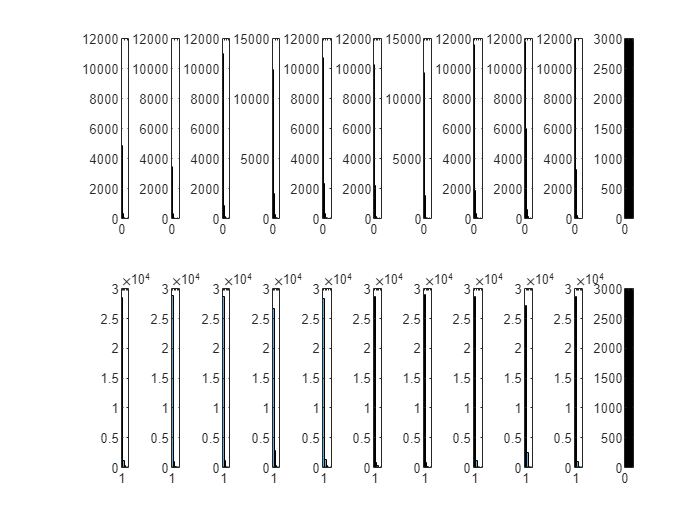

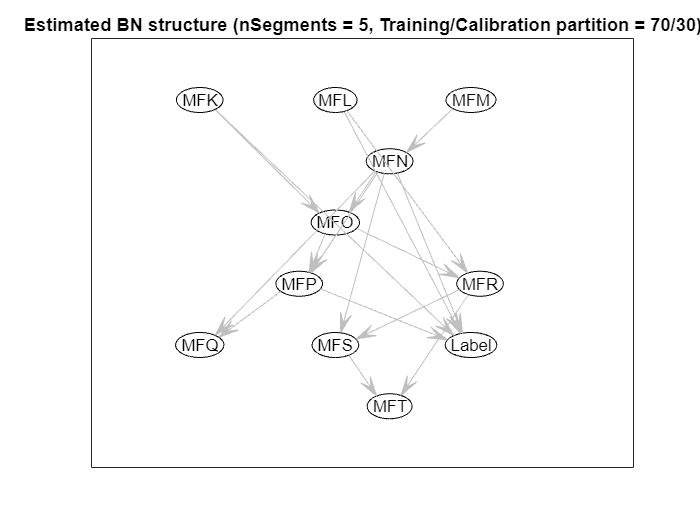

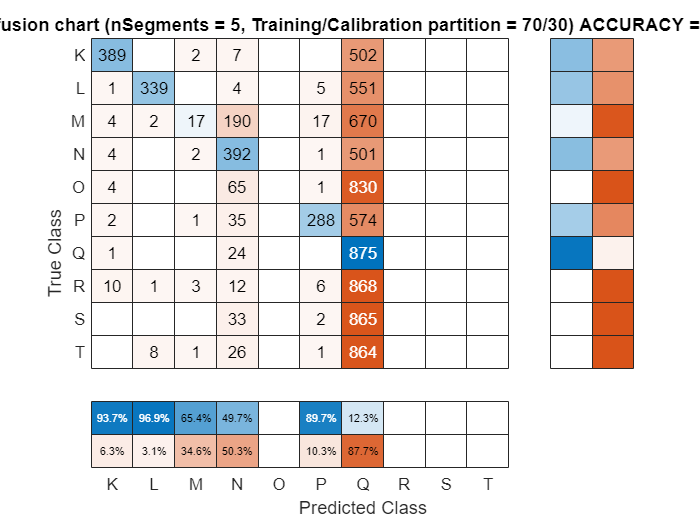

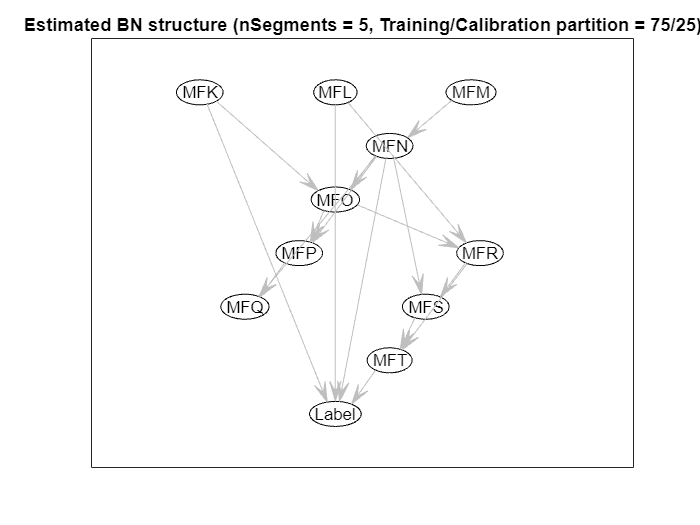

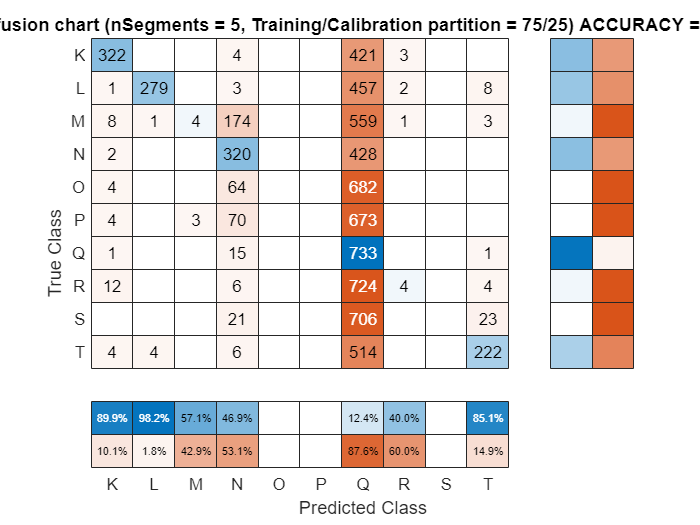

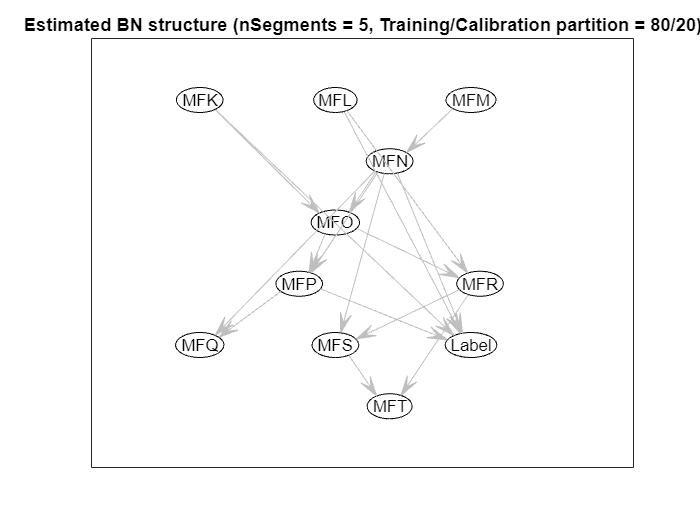

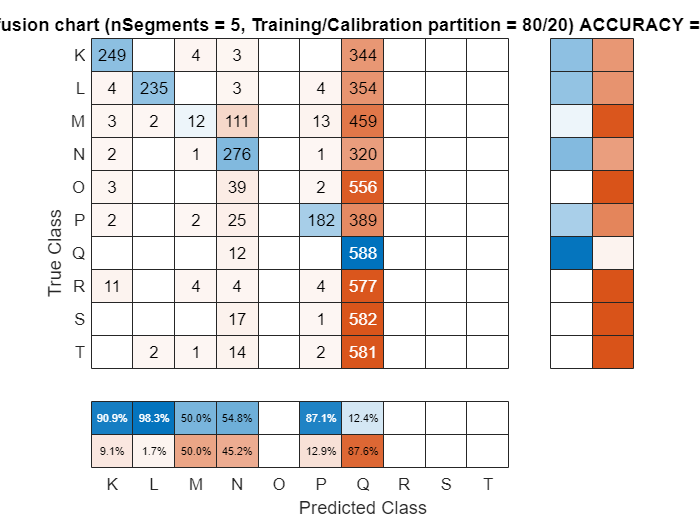

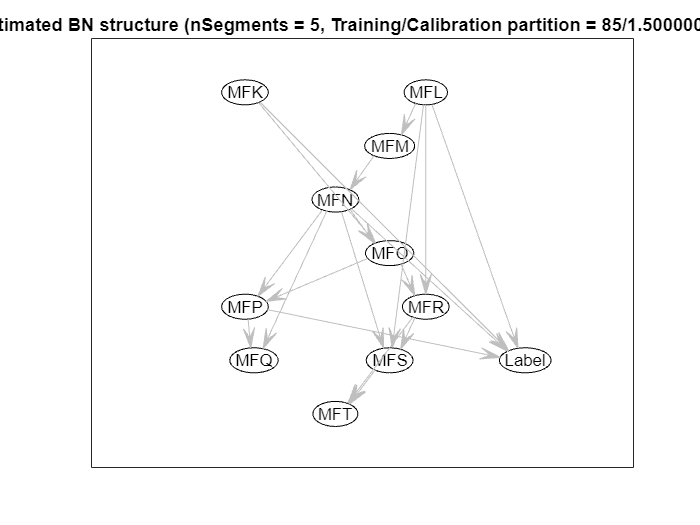

BNtemp = mk_bnet(DAGhat, node_sizes);

for i = 1:col
    BNtemp.CPD{variable(i).node} = tabular_CPD(BNtemp, variable(i).node);
end

BNhat = learn_params(BNtemp, cases);

CPThat = cell(1, col);
for i = 1:col
    s = struct(BNhat.CPD{i});
    CPThat{i} = s.CPT;
end


figure;
draw_graph(BNhat.dag, varLabels);
title(sprintf("Estimated BN structure (nSegments = %d, Training/Calibration partition = %d/%d)", nseg, 100-partition_rate*100, partition_rate*100));

%Classification
engine       = global_joint_inf_engine(BNhat);

if (nseg == nSeg_chosen) && (partition_rate == partition_rate_chosen)
    save services\engine.mat engine variable nseg seg_mat
end
[rowT, colT] = size(dataCal);

try
    for j = 1:rowT
        evidence     = [];
        evidence     = cell(1,colT);
        
        for i = 1:colT-1
           evidence{variable(i).node} = dataCal(j,i);
        end
        [engine, logLikelihood] = enter_evidence(engine, evidence);
        marginal       = marginal_nodes(engine, variable(end).node);
        totProb        = sum(marginal.T(:));
        dataPoint(j).M = marginal.T ./ totProb;
        [~, dataPoint(j).yhat] = max(dataPoint(j).M);
    end
    
    Ypred = categorical([dataPoint.yhat]');
    Ytrue = categorical(dataCal(:,end));
    
    accuracy = sum(Ypred==Ytrue)/length(Ytrue);
    ACCURACY_CAL(nseg_i,partition_rate_i) = accuracy;
    figure;
    cm = confusionmat(Ytrue, Ypred);
    results = confusionchart(cm, class_list, 'ColumnSummary','column-normalized', 'RowSummary', 'row-normalized');
    results.title(sprintf("Confusion chart (nSegments = %d, Training/Calibration partition = %d/%d) ACCURACY = %0.2f%%", nseg, 100-partition_rate*100, partition_rate*100, accuracy*100));
catch
    warning('Problems occured.');
end
    end
end

## NAIVE BAYESIAN CLASSIFICATION STRUCTURE

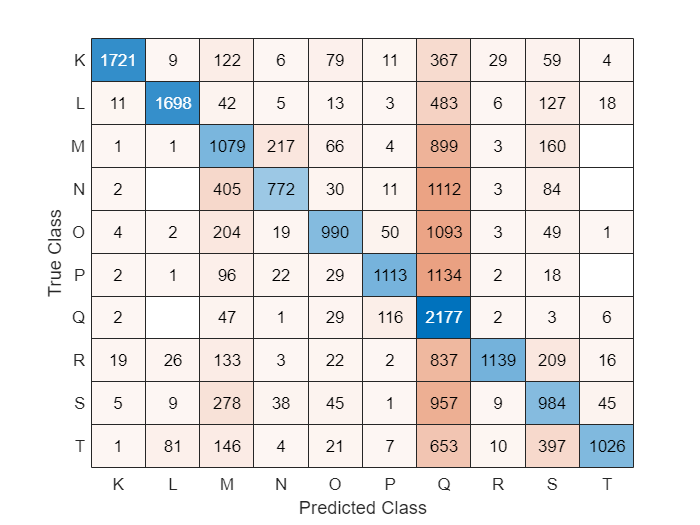

% load extracted_features\Xtrain_extracted.mat Xtrain_extracted
load extracted_features\Xtrain_nMatchedFeatures_table.mat Xtrain_nMatchedFeatures_table
Xtrain_extracted = Xtrain_nMatchedFeatures_table;
load extracted_features\Ytrain.mat Ytrain

% USE VARIABLE NAMED Xtrain_extracted AS TRAINING AND VALIDATING DATA
[nXtrain, nCol] = size(Xtrain_extracted);
% varLabels = ["SP1x", "SP1y", "SP2x", "SP2y", "SP3x", "SP3y", "SP4x", "SP4y", "SP5x", "SP5y","MFK","MFL","MFM","MFN","MFO","MFP","MFQ","MFR","MFS","MFT", "Label"];
varLabels = ["MFK","MFL","MFM","MFN","MFO","MFP","MFQ","MFR","MFS","MFT", "Label"];
class_list = ["K", "L", "M", "N", "O", "P", "Q", "R", "S", "T"];                                    % All classes included in this project
class_list = sort(class_list);

% Ytrain = grp2idx(categorical(Ytrain));
Xtrain_extracted.Label = Ytrain;

cv = cvpartition(nXtrain, "HoldOut", 0.8);
Xtrain_nb_i = training(cv);
Xval_nb_i = test(cv);

Xtrain_nb = Xtrain_extracted(Xtrain_nb_i,:);
Ytrain_nb = Ytrain(Xtrain_nb_i,:);

Xval_nb = Xtrain_extracted(Xval_nb_i,:);
Yval_nb = Ytrain(Xval_nb_i,:);


NBmdl = fitcnb(Xtrain_nb, "Label");
LabelPred = predict(NBmdl, Xval_nb);
LabelPred = convertCharsToStrings(LabelPred);
ConfusionMat1 = confusionchart(Yval_nb,LabelPred);

accuracy_nb = sum(Yval_nb==LabelPred)/length(Yval_nb)

accuracy_nb = 0.5291

save services\naiveBayesMdl.mat NBmdl


## TESTING

Function "sign_language_detect.m" can be used to make prediction either from loaded grayscale image data matrix or from a path-to-image. "Visual" flags can be used to allow visualization and plotting.

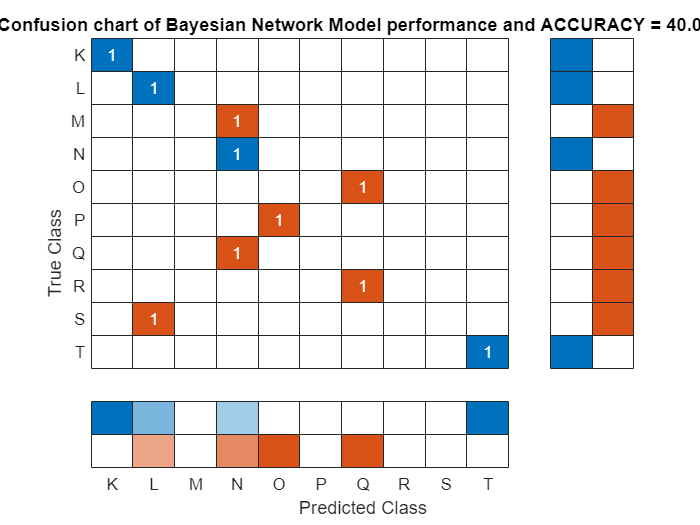

class_list = ["K", "L", "M", "N", "O", "P", "Q", "R", "S", "T"];                                    % All classes included in this project
class_list = sort(class_list);
nClass = length(class_list);
test_data_path = "./data/asl_alphabet_test/asl_alphabet_test";                                     % File path to the directory of test data
nTestSamplePerClass = zeros(nClass, 1);

file_list = dir(test_data_path);
file_list = file_list(3:end);
regex_class = sprintf('%s-%s', class_list(1), class_list(end));
regex_file_name = sprintf('^(?<file_name>[%s]_test.jpg)', regex_class);
test_files_cell = regexpi({file_list.name}, regex_file_name, 'names','lineanchors');
test_files = vertcat(test_files_cell{:});
nXtest = length(test_files);

YtestPredBN = [];
YtestPredNB = [];
YtestTrue = [];

for f = 1:nXtest
    file_name = test_files(f).file_name;
    path_to_image = sprintf(test_data_path + "/" + file_name);

    % Predict with model trained with Bayesian Network
    YtestPredBNf = sign_language_detect(path_to_image, false);
    YtestPredBN = [YtestPredBN; YtestPredBNf];
    
    % Predict with model trained with Naive Bayesian structure
    YtestPredNBf = sign_language_detect_naivebayes(path_to_image, false);
    YtestPredNB = [YtestPredNB; YtestPredNBf];
    
    % Get true class from file name
    YtestTruef = string(file_name(1));
    YtestTrue = [YtestTrue; YtestTruef];
end
% Confusion Chart and Accuracy of the trained Bayesian Network on the test
% data
TestAccuracyBN = sum(YtestPredBN==YtestTrue)/length(YtestTrue);
figure;
cmTestBN = confusionmat(YtestTrue, YtestPredBN);
TestresultsBN = confusionchart(cmTestBN, class_list, 'ColumnSummary','column-normalized', 'RowSummary', 'row-normalized');
TestresultsBN.title(sprintf("Confusion chart of Bayesian Network Model performance and ACCURACY = %0.2f%%", TestAccuracyBN*100));

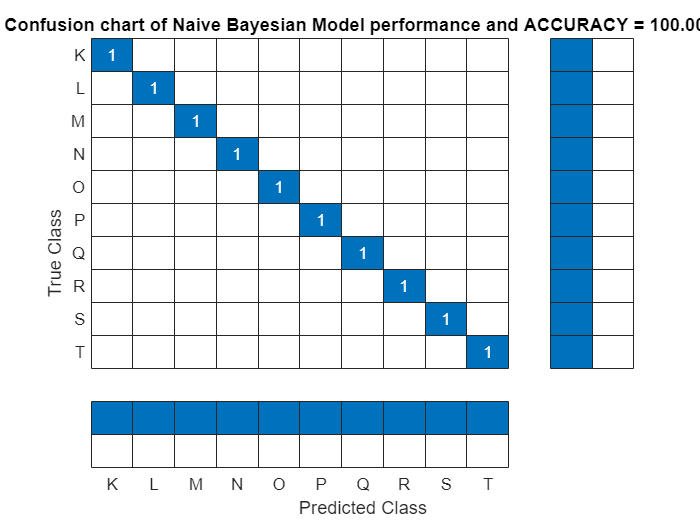

% Confusion Chart and Accuracy of the trained Naive Bayesian structure on the test
% data
TestAccuracyNB = sum(YtestPredNB==YtestTrue)/length(YtestTrue);
figure;
cmTestNB = confusionmat(YtestTrue, YtestPredNB);
TestresultsNB = confusionchart(cmTestNB, class_list, 'ColumnSummary','column-normalized', 'RowSummary', 'row-normalized');
TestresultsNB.title(sprintf("Confusion chart of Naive Bayesian Model performance and ACCURACY = %0.2f%%", TestAccuracyNB*100));